# PASSIVE Radar Data - Processing Data to Output SNR

### This script will, for PASSIVE input data:

- Uses func slice_SNR to calculate the peak power, the noise (how?), the SNR, and the index of the peak power.  

- Generate a Range-Doppler for the defined slice within the input data.

- Plot a large white diamond marker where the peak power is represented in the Range-Doppler.

- Saves the figure as a .PNG

#### Preperation of data

Clear current workspace dialogue box

% Display a dialog box with three options
choice = questdlg('Do you want to clear the Workspace?', ...
    'Clear Workspace?', 'Yes', ...
    'No', 'No');

% Process user's choice
switch choice
    case 'Yes'
        disp('Workspace cleared');
        % Add code for Option 1 here
        clear
    case 'No'
        disp('Workspace not cleared');
        % Add code for Option 2 here
    otherwise
        % Add code for handling other cases
        disp('User closed the dialog without selecting an option.');
        error('Error. Passive data Workspace dialogue box.')
        % Add code for handling other cases
end

Workspace not cleared


#### Preparation of Data Storage Directory

This defines where all data generated from this script will be stored. Sub-folders are also created.

% Display a dialog box with three options
choice = questdlg('Select which device you are operating:', ...
    'User to Select Device', 'Rikki - MacBook', ...
    'Jacob - Laptop', 'Rikki - UCL', 'Rikki - MacBook');
% Initialise variable
pc = [];

% Process user's choice
switch choice
    case 'Rikki - MacBook'
        disp('Rikki - MacBook');
        % Add code for Option 1 here
        pc = 1;
        addpath '/Users/rikkimasson/Documents/MATLAB/experiment_data/2'
        addpath '/Users/rikkimasson/Documents/GitHub/bladeRAD-Rikki/generic_scripts/matlab'
        local_save_directory = "/Users/rikkimasson/Documents/MATLAB/experiment_data/";
        repo_directory = "/Users/rikkimasson/Documents/GitHub";
    case 'Jacob - Laptop'
        disp('Jacob - Laptop');
        % Add code for Option 2 here
        pc = 2
        local_save_directory = "C:\Users\jster\OneDrive - University College London\Processing Project Jacob + Rikki\Data Files";
        repo_directory = "D:\GitHub Repos";
    case 'Rikki - UCL'
        disp('Rikki - UCL');
        % Add code for Option 3 here
        pc = 3
        local_save_directory = "C:\Users\uceerm6\OneDrive - University College London\Documents\Radar_Data\beasley_bladeRAD\";
        repo_directory = "C:\Users\uceerm6\OneDrive - University College London\Documents\GitHub";
    otherwise
        % Add code for handling other cases
        disp('User closed the dialog without selecting an option.');
        error('Error. Active data device selection dialogue box.')
        % Add code for handling other cases
end

Rikki - MacBook


Load workspace

load('my_workspace_baseline_23Jan.mat') % define workspace

Prepare Data

inputstructure = passive; % define your data input structure
inputstructure.name = "Passive"; % define your data input name
% passive_inputdata = inputstructure.range_doppler_slices;
passive_inputdata = inputstructure.CLEANed_range_doppler_slices; % CLEANed uses post DSI data
% User defined ROI indices
passive_roi_indices_rows = 320:420; % input to slice_SNR func to calculate noise of roi
passive_roi_indices_cols = 35:45;   % input to slice_SNR func to calculate noise of roi
passive_signal=zeros(1,length(passive_inputdata)); % [dB] once func populates
passive_noise=zeros(1,length(passive_inputdata)); % [dB] once func populates
passive_noise_abs=zeros(1,length(passive_inputdata)); % absolute mean noise (not dB) once func populates
passive_SNR=zeros(1,length(passive_inputdata)); % [dB] once func populates
passive_slices_range_doppler = createArrays(length(passive_inputdata), size(passive_inputdata{1,1})); % [dB] once func populates
passive_slices_range_doppler_abs = createArrays(length(passive_inputdata), size(passive_inputdata{1,1})); % absolute not dB, once func populates
passive_signal_idx = zeros(1,length(passive_inputdata));

for i=1:length(passive_inputdata)
    [passive_signal(i),...
        passive_noise(i),...
        passive_SNR(i),...
        passive_slices_range_doppler{i},...
        passive_signal_idx(i),...
        passive_noise_abs(i),...
        passive_slices_range_doppler_abs{i}]=slice_SNR(passive_inputdata{1,i}, passive_roi_indices_rows, passive_roi_indices_cols);
end   

### User to Define which range doppler slice to visualise:

k = 73; % define which slice number you want to visualise

#### Preparation of Data Storage Directory

This defines where all data generated from this script will be stored. Sub-folders are also created.

if pc ==1
    experiment_directory = local_save_directory + experiment_number;
    mkdir(experiment_directory); % create directory
    video_directory = experiment_directory + bracket + "videos";
    mkdir(video_directory); % create directory
    figure_directory = experiment_directory + bracket + "figures";
    mkdir(figure_directory); % create directory
elseif pc ==2
    display('pc 2 data storage directories to be defined by User')
elseif pc ==3
    display('pc 3 data storage directories to be defined by User')
else
    display('Undefined by User')
end    

Define Range-Doppler user input configuration

x = inputstructure.range_axis; % x_axis
y = inputstructure.doppler_axis; % .doppler_axis is doppler frequency [Hz] % doppler_velocity_axis; % y_axis
dynamic_range = +inf % +50; % user defined dynamic range to maximise visualisation

dynamic_range = Inf

max_range = 500 % user defined max range to maximise visualisation

max_range = 500

max_doppler = 500 % user defined max doppler to maximise visualisation

max_doppler = 500

Generate Range-Doppler image with scaled colours

figure
figure_title = (inputstructure.name + ' Range Doppler Slice ' ...
    + k + ' of ' + length(passive_inputdata));
fig = figure;
imagesc(x,y,passive_slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Frequency [Hz]');
xlabel('Range (m)') ;

User to define limits of the colorbar

clim([-100 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;
hold on

Return row and column index positions for peak signal index

[idx_doppler, idx_range] = ind2sub(size(passive_slices_range_doppler{1,k}),passive_signal_idx(k))

idx_doppler = 264

idx_range = 4

Convert index row and column into doppler and range using passive. axis

idx_range_axis = inputstructure.range_axis(idx_range)

idx_range_axis = 44.9689

idx_doppler_axis = inputstructure.doppler_axis(idx_doppler)

idx_doppler_axis = 26

Plot peak signal on top of Range-Doppler as large white diamond

plot(idx_range_axis, idx_doppler_axis...
    , "diamondk", "MarkerFaceColor","w",...
    'MarkerSize', 10)
hold off

Save generated image as .PNG

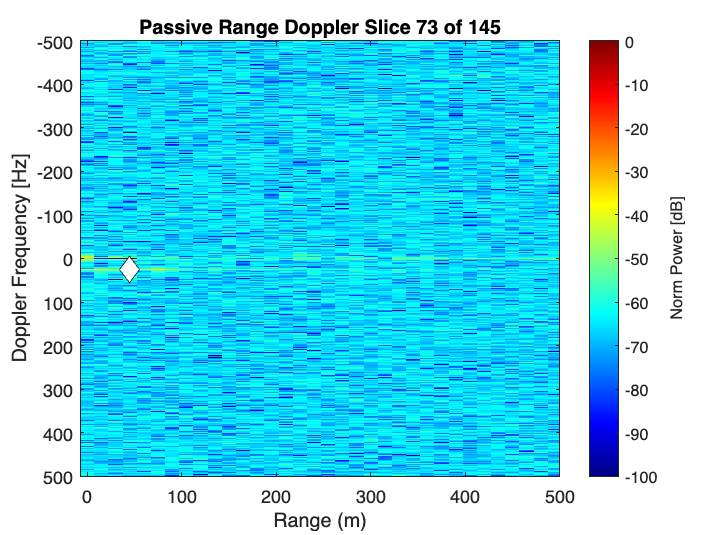

fig_name = figure_directory + bracket + figure_title;
savefig(figure_title)
saveas(fig, fig_name, 'png')

## Quantify Signal and Noise

passive_signal; % output from slice_SNR function
passive_noise; % output from slice_SNR function


## User defined SNR input to the awgn function

User defined level of noise desired

passive_user_defined_noise = 10  % User defiend noise [?dB?]

passive_user_defined_noise = 10

Take the input data complex array and apply the awgn function

passive_inputdata_plus_noise = createArrays(length(passive_inputdata),...
    size(passive_inputdata{1,1}));
for i=1:length(passive_inputdata)
    passive_inputdata_plus_noise{1,i} = awgn(passive_inputdata{1,i}, passive_user_defined_noise,...
        'measured'); % complex + awgn
end

Convert the noise induced complex array to power using the slice_SNR func

passive_signal_plus_noise=zeros(1,length(passive_inputdata)); % [dB] once func populates
passive_noise_plus_noise=zeros(1,length(passive_inputdata)); % [dB] once func populates
passive_noise_plus_noise_abs=zeros(1,length(passive_inputdata)); % absolute mean noise (not dB) once func populates
passive_SNR_plus_noise=zeros(1,length(passive_inputdata)); % [dB] once func populates
passive_slices_range_doppler_plus_noise = createArrays(length(passive_inputdata), size(passive_inputdata{1,1})); % [dB]
passive_slices_range_doppler_plus_noise_abs = createArrays(length(passive_inputdata), size(passive_inputdata{1,1})); % Absolute
passive_signal_idx_plus_noise = zeros(1,length(passive_inputdata));

for i=1:length(passive_inputdata)
    [passive_signal_plus_noise(i),passive_noise_plus_noise(i),passive_SNR_plus_noise(i),...
        passive_slices_range_doppler_plus_noise{i},...
        passive_signal_idx_plus_noise(i), passive_noise_plus_noise_abs(i),...
        passive_slices_range_doppler_plus_noise_abs{i}]=slice_SNR(passive_inputdata_plus_noise{1,i}, passive_roi_indices_rows, passive_roi_indices_cols);
end  

Visualise the slice chosen by the user both with & without awgn applied at complex and dB stages

figure
figure_title = (inputstructure.name +...
    ' Range Doppler Slice '...
    + k + ' of ' + length(passive_inputdata));
fig = figure;

subplot(2, 1, 1);
imagesc(x,y,passive_slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)');
% User to define limits of the colorbar
clim([-dynamic_range 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

subplot(2, 1, 2);
imagesc(x,y,passive_slices_range_doppler_plus_noise{1, k},[-dynamic_range 0])
title(figure_title + ' +' + passive_user_defined_noise + 'dB Noise at Complex Stage');
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)');
% User to define limits of the colorbar
clim([-dynamic_range 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

Save figures to data directory

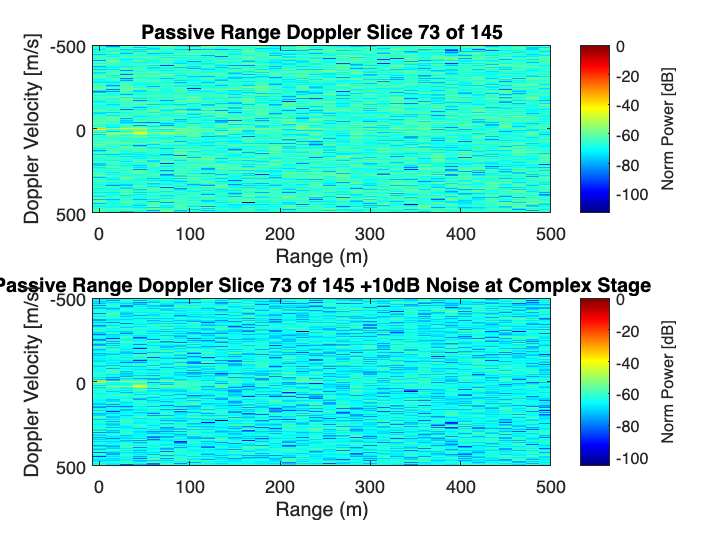

fig_name = figure_directory + bracket + figure_title;
savefig(figure_title)
saveas(fig, fig_name + " baseline to noise comparison", 'png')

## Plot SNR against Time (?) for all slices of Passive data

passive_SNR_delta = passive_SNR - passive_SNR_plus_noise;
figure
figure_title = (inputstructure.name + ' SNR for '...
    + length(passive_inputdata) + ' Slices');
fig = figure;
plot(1:length(passive_SNR), passive_SNR, ...
    1:length(passive_SNR_plus_noise), passive_SNR_plus_noise, ...
    1:length(passive_SNR_delta), passive_SNR_delta)
title(figure_title);
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("SNR", 'SNR + Noise', 'location', 'bestoutside')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor

Save figure to repo

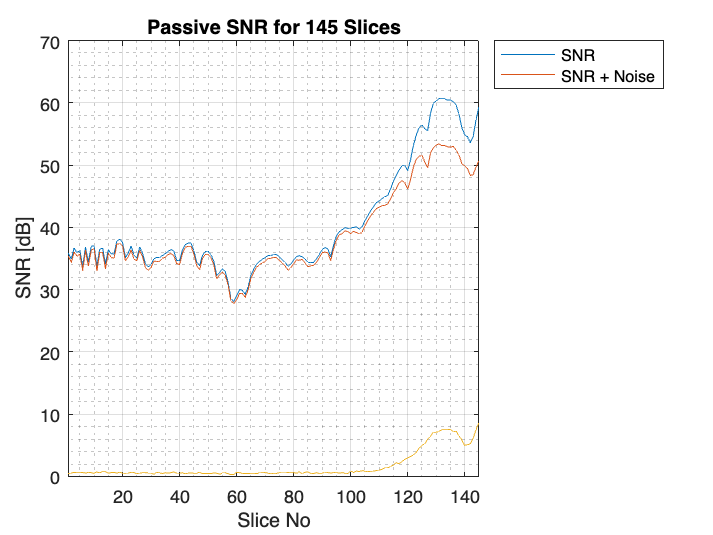

fig_name = figure_directory + bracket + figure_title;
savefig(figure_title)
saveas(fig, fig_name, 'png')

Mean of all Slices - Signal, Noise & SNR

% SNR
passive_mean_SNR = mean(passive_SNR) % [dB]

passive_mean_SNR = 40.2718

passive_mean_SNR_plus_noise = mean(passive_SNR_plus_noise) % [dB]

passive_mean_SNR_plus_noise = 38.6285

passive_mean_SNR_delta = passive_mean_SNR - passive_mean_SNR_plus_noise

passive_mean_SNR_delta = 1.6433


% Signal % not required becuase it's unchanged but kept for completeness
passive_mean_signal = mean(passive_signal) % [dB]

passive_mean_signal = -25.1117

passive_mean_signal_plus_noise = mean(passive_signal_plus_noise) % [dB]

passive_mean_signal_plus_noise = -25.1157


% Noise
passive_mean_noise = mean(passive_noise) % [dB]

passive_mean_noise = -65.3835

passive_mean_noise_plus_noise = mean(passive_noise_plus_noise) % [dB]

passive_mean_noise_plus_noise = -63.7442

passive_mean_noise_delta = passive_mean_noise - passive_mean_noise_plus_noise

passive_mean_noise_delta = -1.6393


disp(['Discuss with MR']);

Discuss with MR


% Noise delta and Signal delta comparable (expected), but the vlaue changed
% and it's relationship to the SNR vlaue input to the awgn func needs to be
% examined.


## Create video of Passive range-Doppler slices

fig =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [1 1 1]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

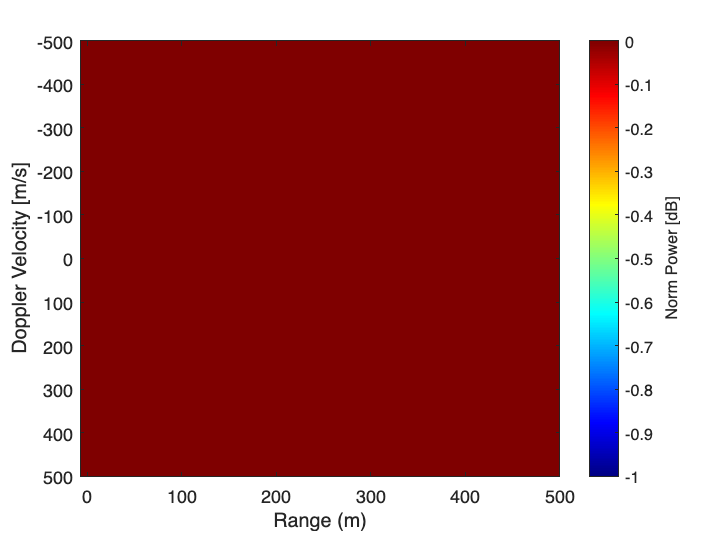

if inputstructure.name == "Passive"
    if pc ==1
        video_name = video_directory...
            + bracket + "SNR Passive Data"...
            + ".avi";
    elseif pc ==2
        display('pc 3 type path undefined by User')
    elseif pc ==3
        display('pc 3 type path undefined by User')
    else
        display('Undefined by User')
    end    
    video_title = "SNR Passive Data";
    dynamic_range = +inf;
    max_range = 500;
    max_doppler = 500;
    frame_rate = 1/(capture_duration/passive.number_cpi);
    createVideo(passive_slices_range_doppler,frame_rate,...
        passive.range_axis,max_range,...
        passive.doppler_axis,max_doppler,...
        dynamic_range,video_name,video_title);
end

## Plot Signal Peak and Matrix Index Across All Slices

figure
fig = figure

fig =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties


subplot(2, 1, 1);
plot(1:length(passive_signal_idx), passive_signal_idx)
hold on
ylabel('Matrix Index Position');
xlabel('Slice Number');  
% ylim([- 120 120]) % ([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf max_range]);   % Range Limit
grid minor 

subplot(2, 1, 2);
plot(1:length(passive_signal), passive_signal)
title(figure_title + ': Signal Peak [dB]');
ylabel('Signal Peak [dB]');
xlabel('Slice Number') ;  
grid minor 
hold off

Save figure to repo

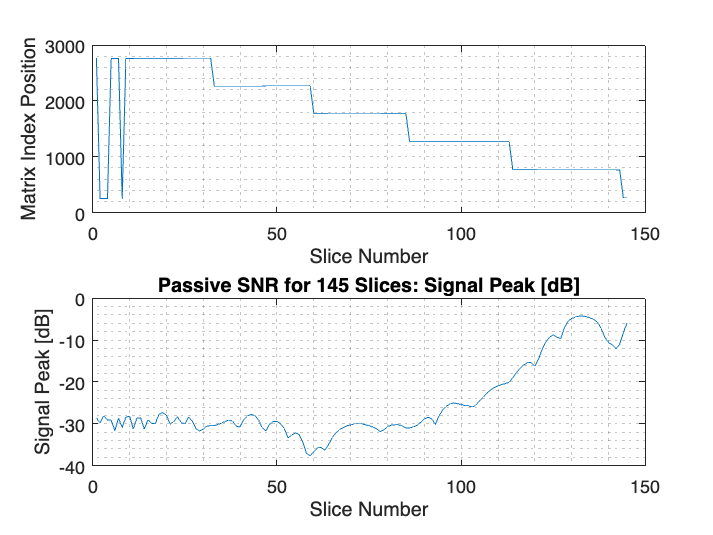

fig_name = figure_directory + bracket + figure_title + ' Signal Peak';
savefig(figure_title)
saveas(fig, fig_name + " Signal Peak and Matrix Index Position", 'png')